clear

syms theta1 theta2 theta3 theta4 theta5 theta6

A = [  0     -1     0.15
      200     0      0
     theta3 theta4 theta5 ];
B = [  0
       0
     theta6];
C = [0 1 0];
graybox = struct('A',A,'B',B,'C',C);
clear theta1 theta2 theta3 theta4 theta5 theta6

A = [-19.4230192310286  5.33689098338979    3.49995019807661
     -12.1311290167373 -0.602045011451299 -11.4818883114291
      16.3130278947638 14.8960978823999    -4.97493575752010];
B = [-1.72337203677241
     -0.644436459399537
      1.72830662854464 ];
C = [10.8506957537365 -6.92573694290204 8.23730466120267];
blackbox = ss(A,B,C,0);
clear A B C

sol = gray3sid(blackbox, graybox, 'Method','similarityTransform');
disp(sol.parameters.')

$$\left(\begin{array}{cccc} \theta_{3} & \theta_{4} & \theta_{5} & \theta_{6} \end{array}\right)$$

disp(sol.parameter_values.')

 -600.0000  -10.0000  -25.0000 -100.0000



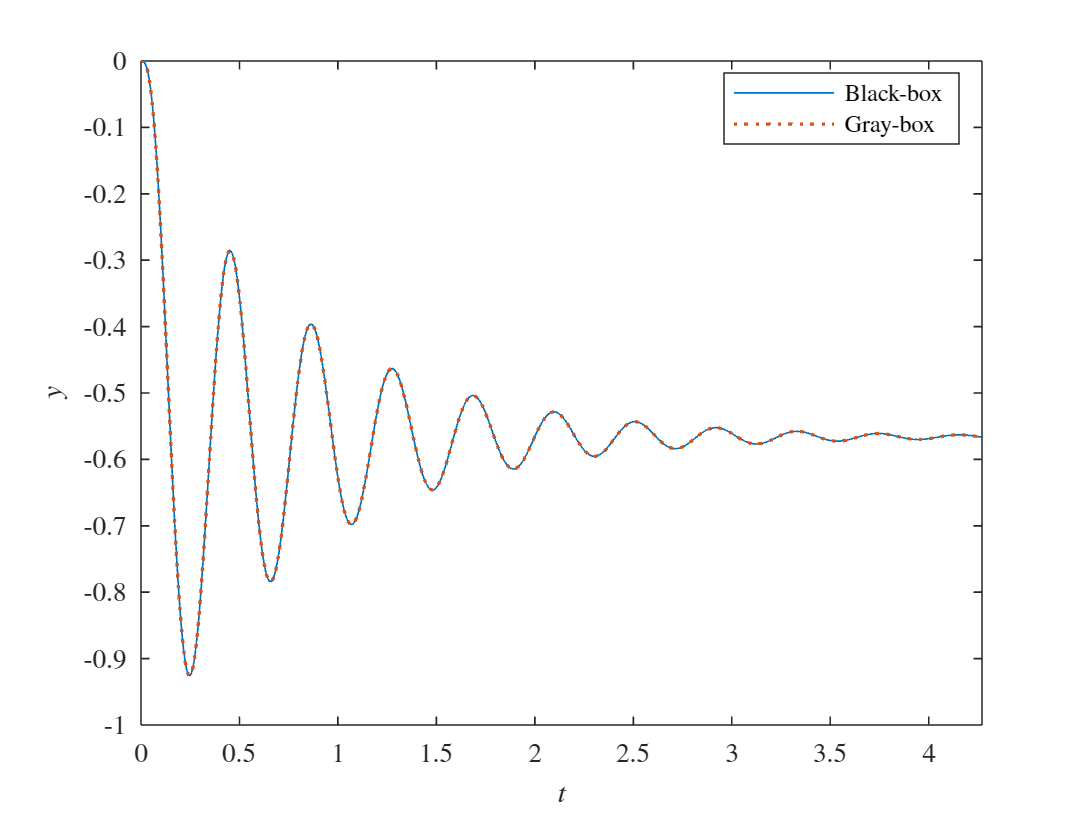


figure
hold on
[y,t] = step(blackbox);
plot(t, y, '-', 'DisplayName','Black-box', 'LineWidth',0.5)
[y,t] = step(sol.sys);
plot(t, y, ':', 'DisplayName','Gray-box',  'LineWidth',1)
legend('Location','best')
xlabel('$t$')
ylabel('$y$')
xlim([min(t) max(t)])
box on

clear

syms theta1 theta2 theta3

A = [1 theta1
     1 -3];
B = [theta2
       1   ];
C = [1 0];
graybox = struct('A',A,'B',B,'C',C);
clear theta1 theta2 theta3

A = [177.776963379520  -496.711190701046
      64.3476596331393 -179.776963379520];
B = [3.72290476694050
     1.33660669226990];
C = [14.3600000000000  -37.7530000000000];
blackbox = ss(A,B,C,0);
clear A B C

sol = gray3sid(blackbox, graybox, 'Method','DCP');

DCP method stopped because the size of the current step is less than StepTolerance


disp(sol.parameters.')

$$\left(\begin{array}{cc} \theta_{1} & \theta_{2} \end{array}\right)$$

disp(sol.parameter_values.')

   -5.0000    3.0000



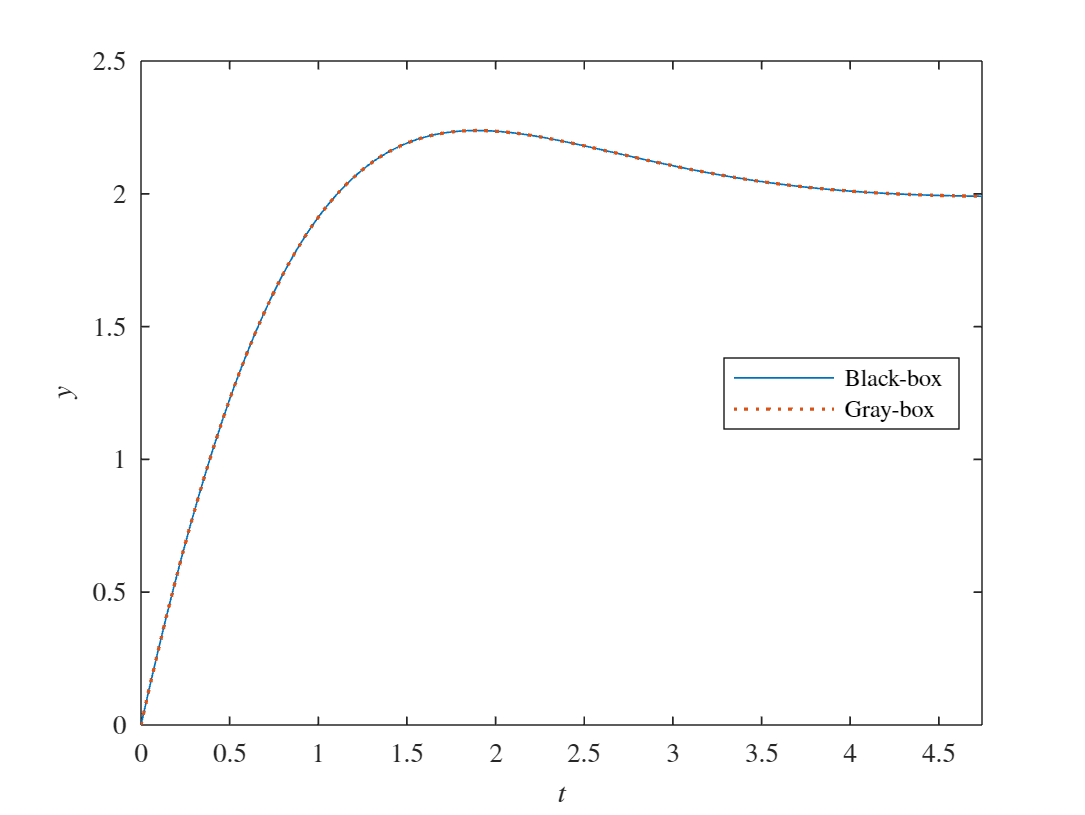


figure
hold on
[y,t] = step(blackbox);
plot(t, y, '-', 'DisplayName','Black-box', 'LineWidth',0.5)
[y,t] = step(sol.sys);
plot(t, y, ':', 'DisplayName','Gray-box',  'LineWidth',1)
legend('Location','best')
xlabel('$t$')
ylabel('$y$')
xlim([min(t) max(t)])
box on

clear

theta = sym('theta', [1 14]);
vals = [-0.0558 0.5980 -3.0500 -0.9968 -0.1150 0.3880 0.0805 0.0802 -0.0318 -0.4650 0.0415 0.0073 -0.4750 0.1430];

A = [theta(1) theta(4) theta(8) theta(11)
     theta(2) theta(5) theta(9)    0
     theta(3) theta(6) theta(10)   0
        0     theta(7)    1        0    ];
B = [theta(12)    0
     theta(13) theta(12)
     theta(14) theta(14)
        0         0     ];
C = [0 1 0 0
     0 0 0 1];

k = [3 6 7 10];
A = subs(A, theta(k), vals(k));
B = subs(B, theta(k), vals(k));
C = subs(C, theta(k), vals(k));
graybox = struct('A',A,'B',B,'C',C);

S = [-0.0072  0.2254  0.3269 -0.0359
     -0.0674 -0.2287  0.1437  0.0147
     -0.0070  0.4030 -1.0964 -0.8850
     -1.6247  1.2346  0.6572  1.2397];
A = inv(S) * double(subs(A,theta,vals)) * S;
B = inv(S) * double(subs(B,theta,vals));
C =          double(subs(C,theta,vals)) * S;
blackbox = ss(A,B,C,0);
clear A B C S k

sol = gray3sid(blackbox, graybox, 'Method','similarityTransform');
disp(sol.parameters.')

$$\left(\begin{array}{cccccccccc} \theta_{1} & \theta_{11} & \theta_{12} & \theta_{13} & \theta_{14} & \theta_{2} & \theta_{4} & \theta_{5} & \theta_{8} & \theta_{9} \end{array}\right)$$

disp(sol.parameter_values.')

   -0.0558    0.0415    0.0073   -0.4750    0.1430    0.5980   -0.9968   -0.1150    0.0802   -0.0318

